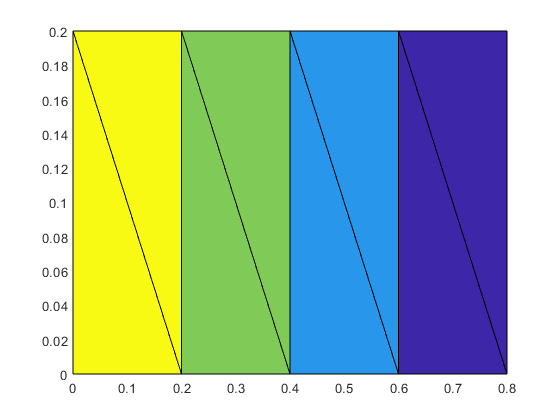

%三角形单元水平悬臂梁应力分析
%悬臂梁长0.8m.高0.2m，厚0.1m
%梁右端上侧受到竖直向下的力，大小为1kN。
%计算结果：单元应力与悬臂梁三角形单元划分图
%苏天宇S230200178
clear;clc;
%单位：m;kN;Pa;
E=210e7;%弹性模量
u=0.4;%泊松比
q=1;%外载荷
t=0.1;%梁厚度
node=[1 0 0 0;
    2 0.2 0 0;
    3 0.4 0 0;
    4 0.6 0 0;
    5 0.8 0 0;
    6 0 0.2 0;
    7 0.2 0.2 0;
    8 0.4 0.2 0;
    9 0.6 0.2 0;
    10 0.8 0.2 0];%节点坐标
ele=[1 1 2 6;
    2 2 6 7;
    3 2 3 7;
    4 3 7 8;
    5 3 4 8;
    6 4 8 9;
    7 4 5 9;
    8 5 9 10];%单元信息
num_ele=size(ele,1);
n_ele=length(ele(:,1));
dof=length(node(:,1))*2;
f=ones(dof,1)*1e8;
fl=zeros(6,1);
x=ones(dof,1)*1e6;%位移矩阵
K=zeros(dof);
stress=zeros(n_ele,1);
for i=1:n_ele
    k_ele=TriangleElementStiffness(E,u,t,node(ele(i,2:4),2:4));
    K=assemTriangle(K,k_ele,ele(i,2),ele(i,3),ele(i,4));
end
%力边界条件
%10节点具有沿y轴竖直向下力
for i=3:10
    f(i)=0;
end
for i=13:19
    f(i)=0;
end
f(20)=1;
%位移边界条件
%左端固定
x(1)=0;
x(2)=0;
x(11)=0;
x(12)=0;
index=[];      %未知自由度的索引
p=[];          %未知自由度对应的节点力矩阵
for i=1:dof
    if x(i)~=0
        index=[index,i];
        p=[p;f(i)];
    end
end
x(index)=K(index,index)\p;    %高斯消去
f=K*x;
stress=zeros(num_ele,3);
x1=node(:,2)+x(1:2:20);
y1=node(:,3)+x(2:2:20);
figure;
for i=1:n_ele
   x1=[x(2*ele(i,2)-1);x(2*ele(i,2));x(2*ele(i,3)-1);x(2*ele(i,3));x(2*ele(i,4)-1);x(2*ele(i,4))];
    stress(i,:)=TriangleElementStress(E,u,node(ele(i,2:4),2:3),x1,1);   %单元应力计算
    patch(node(ele(i,2:4),2),node(ele(i,2:4),3),stress(i,1)); 
end
hold on;

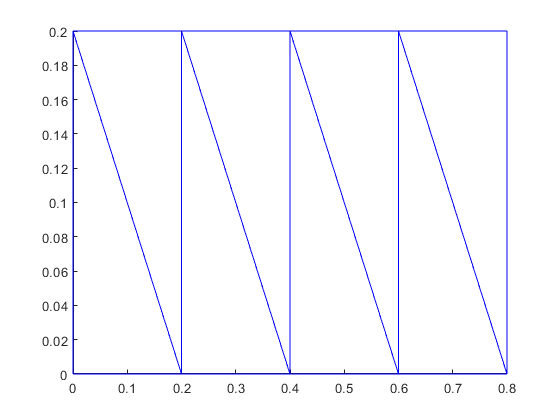

figure;
for i=1:n_ele
    patch(node(ele(i,2:4),2),node(ele(i,2:4),3),'w','FaceColor','none','LineStyle','-','EdgeColor','b');
    hold on;
end